# Frequency responses to temperature

clearvars -except hkg hkg2 xxkg xxkg2 
ReFs = 20;

## Constant temp

SINGLE FISH

hkg(63)

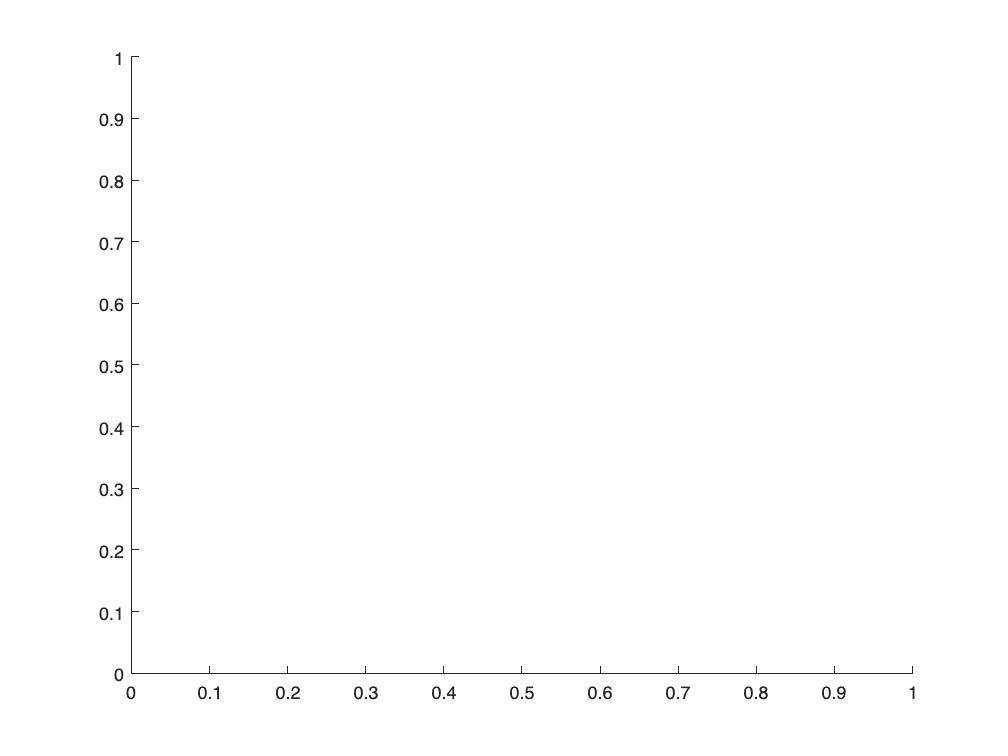

k = 63;
%regularize data
[~, singleconstfreq, singleconstanttemp, ~] = k_dataprepper(hkg(k), 1, ReFs);

% Estimate transfer function from data
[singleconstanttxy, singleconstantf] = tfestimate(singleconstanttemp, singleconstfreq, 1024, 1000, [], 1/ReFs);

MULTI FISH

hkg2(33)

k = 33;
[~, multiconstantfreq, multiconstanttemp, ~] = k_dataprepper(hkg2(k), 3, ReFs);

  [multiconstanttxy, multiconstantf] = tfestimate(multiconstanttemp, multiconstantfreq, 1024, 1000, [], 1/ReFs);


## Chaning temp

SINGLE FISH

xxkg(14)

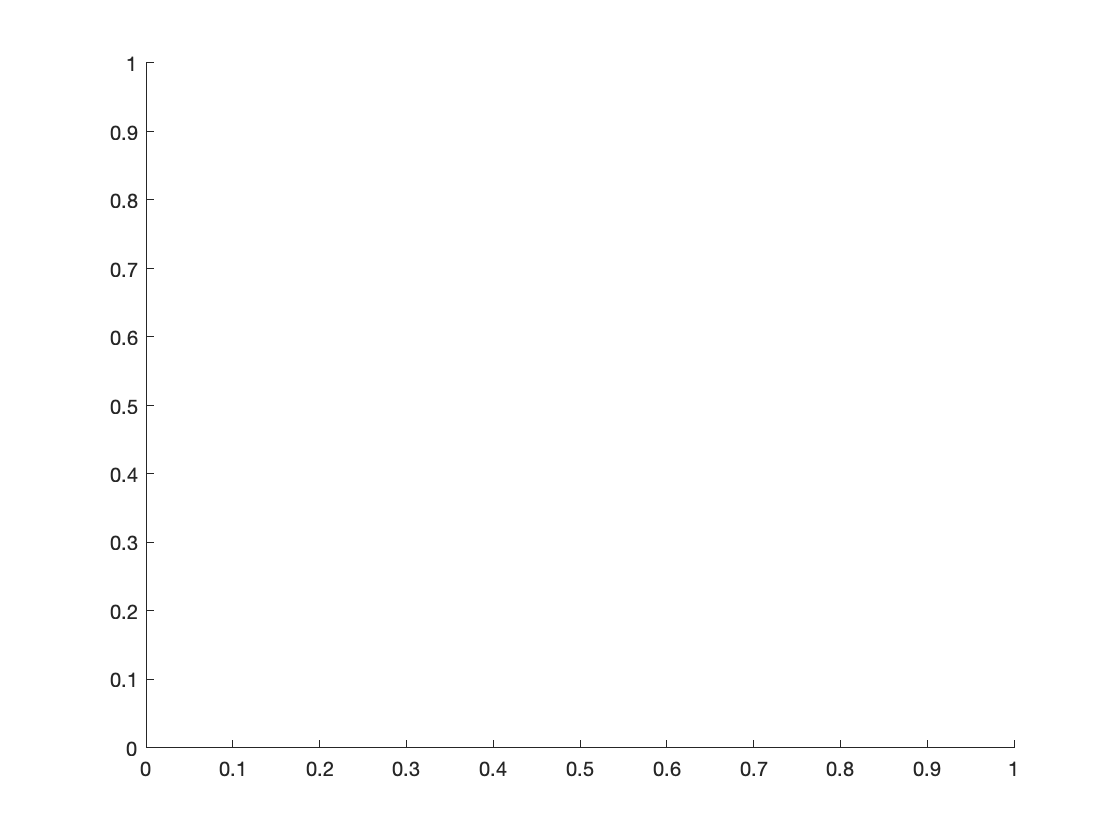

k = 14;
[~, singlechangefreq, singlechangetemp, ~] = k_dataprepper(xxkg(k), 1, ReFs);

[singlechangetxy, singlechangef] = tfestimate(singlechangetemp, singlechangefreq, 1024, 1000, [], 1/ReFs);

MULTIFISH

hkg2(16)

k = 16;
[~, multichangefreq, multichangetemp, ~] = k_dataprepper(hkg2(k), 3, ReFs);

[multichangetxy, multichangef] = tfestimate(multichangetemp, multichangefreq, 1024, 1000, [], 1/ReFs);

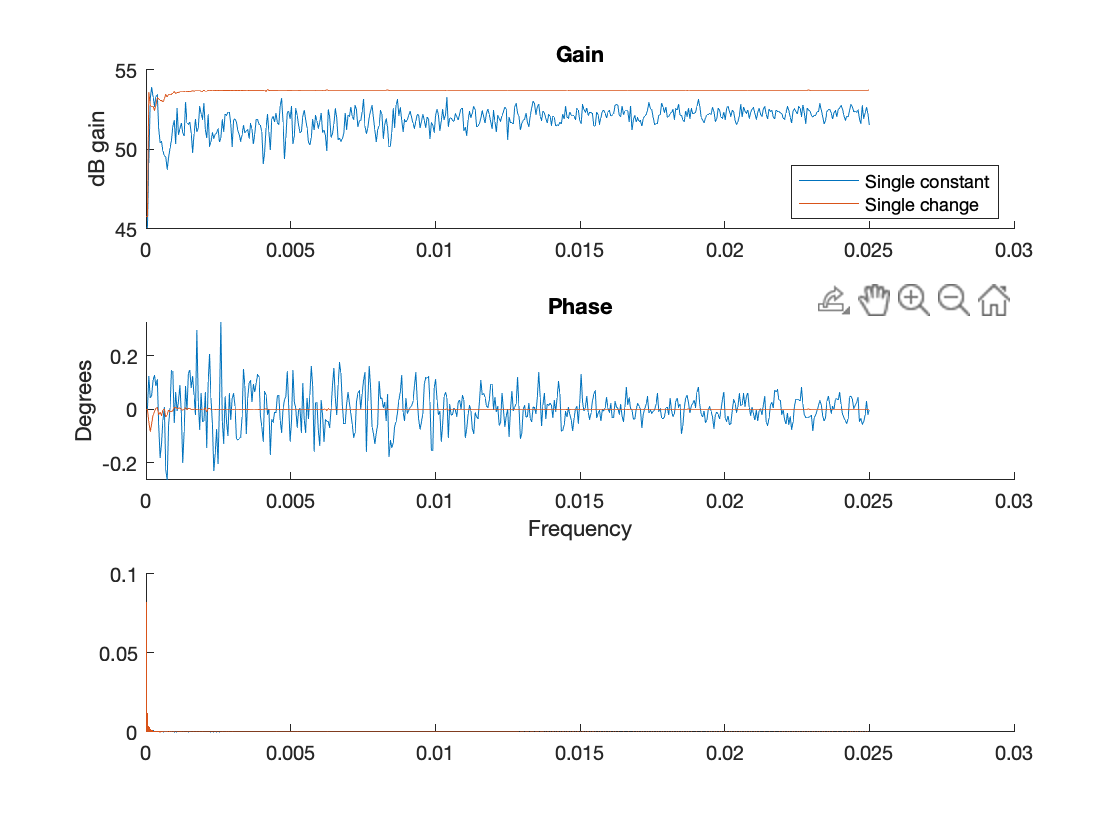

% Plot Bode plot
  figure(112); clf; title('Changed temp');
        ax(1) = subplot(311); hold on; %xlim([0 1]);
            loglog(singleconstantf, mag2db(abs(singleconstanttxy)), 'DisplayName', 'Single constant');
            loglog(singlechangef, mag2db(abs(singlechangetxy)), 'DisplayName', 'Single change');
            title('Gain');
            ylabel('dB gain');
            legend('Location','southeast');

        ax(2) = subplot(312); hold on; %xlim([0 1]);
            semilogx(singleconstantf, phase(singleconstanttxy));
            semilogx(singlechangef, phase(singlechangetxy));
          
            title('Phase');
            ylabel('Degrees');
            xlabel('Frequency');


               
        %solochangeF = fftmachine(singlchangefreq, 1/ReFs);
        %soloconstantF = fftmachine(singlchangefreq, 1/ReFs);
        solochangeT = fftmachine(singlechangetemp - mean(singlechangetemp), 1/ReFs, 11);
        soloconstantT = fftmachine(singleconstanttemp - mean(singleconstanttemp), 1/ReFs, 11);

        ax(3) = subplot(313); hold on; %xlim([0 1]);

        semilogx(soloconstantT.fftfreq, soloconstantT.fftdata);
        semilogx(solochangeT.fftfreq, solochangeT.fftdata);


       linkaxes(ax, 'x');

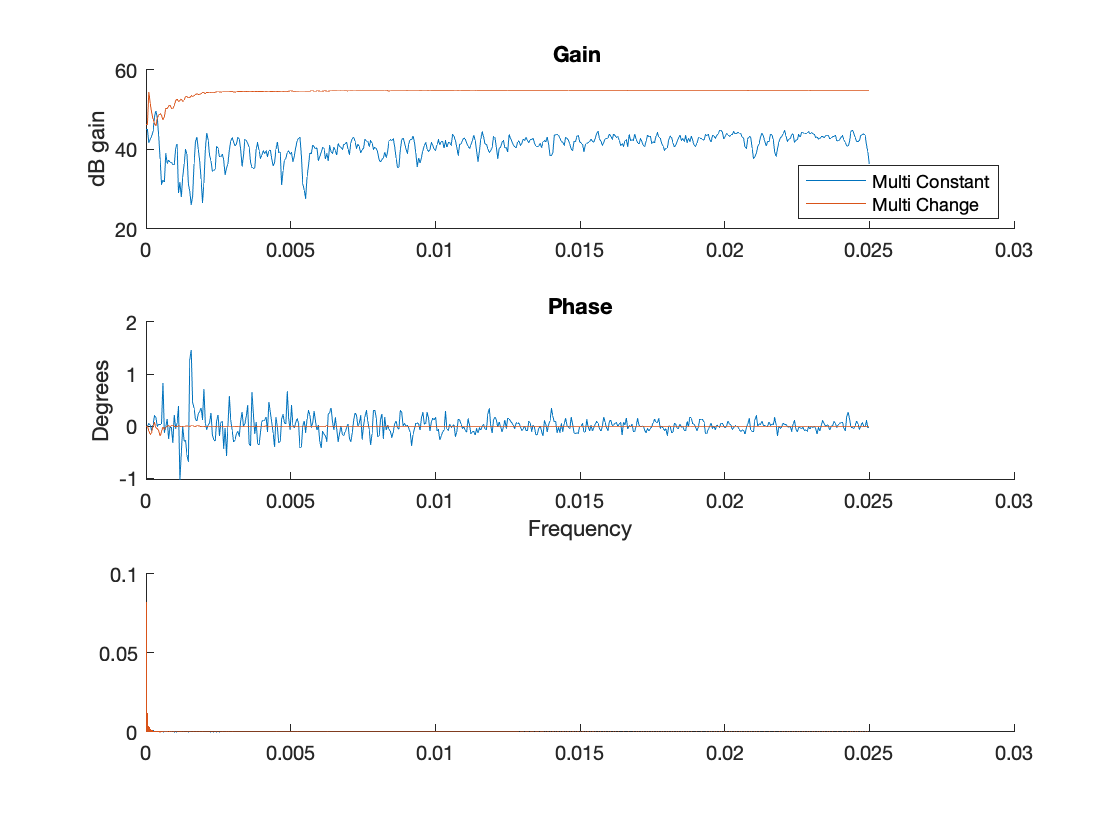

% Plot Bode plot
  figure(111); clf; title('Constant temp');
        xax(1) = subplot(311); hold on; %xlim([0 1]);
            loglog(multiconstantf, mag2db(abs(multiconstanttxy)), 'DisplayName', 'Multi Constant');
            loglog(multichangef, mag2db(abs(multichangetxy)), 'DisplayName', 'Multi Change');
            title('Gain ');
            ylabel('dB gain');
            legend('Location','southeast');

        xax(2) = subplot(312); hold on; %xlim([0 1]);
            semilogx(multiconstantf, phase(multiconstanttxy));
            semilogx(multichangef, phase(multichangetxy));
            title('Phase');
            ylabel('Degrees');
            xlabel('Frequency');
            
               
        %solochangeF = fftmachine(singlchangefreq, 1/ReFs) ;
        %soloconstantF = fftmachine(singlchangefreq, 1/ReFs);
        multichangeT = fftmachine(multichangetemp - mean(multichangetemp), 1/ReFs, 11);
        multiconstantT = fftmachine(multiconstanttemp - mean(multiconstanttemp), 1/ReFs, 11);

        xax(3) = subplot(313); hold on; %xlim([0 1]);

        semilogx(soloconstantT.fftfreq, soloconstantT.fftdata);
        semilogx(solochangeT.fftfreq, solochangeT.fftdata);
        
        linkaxes(xax, 'x');

% solochangeF = fftmachine(singlechangefreq, 1/ReFs);
% soloconstantF = fftmachine(singlechangefreq, 1/ReFs);

Unrecognized function or variable 'singlchangefreq'.

% solochangeT = fftmachine(singlchangetemp, 1/ReFs);
% soloconstantT = fftmachine(singlchangetemp, 1/ReFs);
% 
% dualchangeF = fftmachine(singlchangefreq, 1/ReFs);
% dualconstantF = fftmachine(singlchangefreq, 1/ReFs);
% daulchangeT = fftmachine(singlchangetemp, 1/ReFs);
% daulconstantT = fftmachine(singlchangetemp, 1/ReFs);





